# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 9, 2020

- Location: Locomotion Laboratory

- Subject: LG

- Quarq calibration factor: 327

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 22.0

- Humidity (%): 28.4

- Pressure (mmHg): 636            

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 7;
code = {'LG'};
sex = {'M'};
age = 41;
mass = 140; %lb
height = 1.78; %m

T = table(number,code,sex,age,mass,height)

T = 1×6 table
    number     code      sex     age    mass    height
    ______    ______    _____    ___    ____    ______

      7       {'LG'}    {'M'}    41     140      1.78 


## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.06; 0.12; 0.15];
listHang = listPerc * mass

listHang =     8.4000
   16.8000
   21.0000


### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

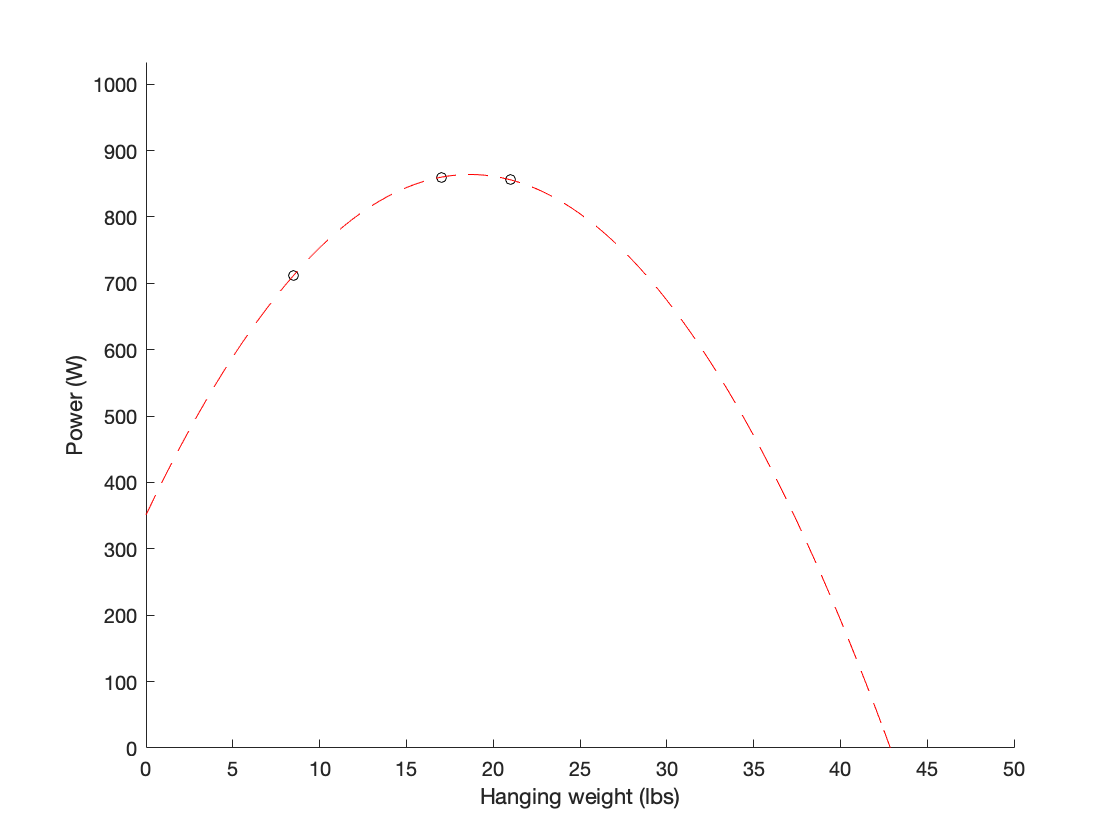

x = [8.5; 17; 21]; % hanging weight
x_ = [149; 104; 80]; % cadence
y = [712; 860; 856]; % power output

% fit curve: power vs hang
% [c, ~, ~] = fit(x,y,'poly2','Lower',[-Inf -Inf 0],'Upper',[Inf Inf 0]);
[c, ~, ~] = fit(x,y,'poly2');

new_x = 0:50/100:50;
new_y = c.p1*new_x.^2+c.p2*new_x+c.p3;

% plot curve: power vs hang
scatter(x,y,25,'k');
hold on
plot(new_x,new_y,'r-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 864.02 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 18.50 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      2     3     1


randperm(3)

ans =      2     3     1


randperm(3)

ans =      3     1     2


### Experimental results

Record results to array then convert to table.

data = [
    7, 1, 1, 18.5, 876, 108; 
    7, 2, 1, 18.5, 855, 101; 
    7, 3, 1, 18.5, 848, 104;
    7, 3, 2, 18.5, 775, 99;
    7, 1, 2, 18.5, 862, 106;
    7, 2, 2, 18.5, 840, 103;
    7, 2, 3, 18.5, 792, 101;
    7, 3, 3, 18.5, 835, 104;
    7, 1, 3, 18.5, 857, 102;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       7           1          1          18.5          876       108  
       7           2          1          18.5          855       101  
       7           3          1          18.5          848       104  
       7           3          2          18.5          775        99  
       7           1          2          18.5          862       106  
       7           2          2          18.5          840       103  
       7           2          3          18.5          792       101  
       7           3          3          18.5          835       104  
       7           1          3          18.5          857       102  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3              865         105.33   
        2            3              829         101.67   
        3            3           819.33         102.33   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          9.8489        3.0551   
        2            3          32.909        1.1547   
        3            3           38.94        2.8868   
